# Numerical Jacobian approximation

clear, clc
set_demo_defaults

In some case it may not be feasible to derive the analytic expression for the Jacobian, or as we shall see it is simply not worth to derive the Jacobina for a one time clculation. In those cases, the Jacobian matrix can be approximated numerically with simple finite differences. This is also useful in testing if the analytic Jacobian has been implemented correctly.

## Sparsity pattern of the Jacobian

%% Grid and operators
Pi = 0.3;
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 10;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
fs = ones(Grid.Nx,1);   % r.h.s
M = Grid.dx/2*abs(G);   % mean operator

%% Residual and Jacobian for unconfined flow
H   = @(h) spdiags(M*h,0,Grid.Nfx,Grid.Nfx);    % diagonal matrix with hD ave on faces
dH  = @(h) spdiags(G*h,0,Grid.Nfx,Grid.Nfx);    % diagonal matrix with G*hD 
res = @(h) D*(H(h)*G*h) + fs;                   % residual vector
Jac = @(h) D*(H(h)*G+dH(h)*M);                  % Jacobian matrix

then we need a test vector that should be non zero

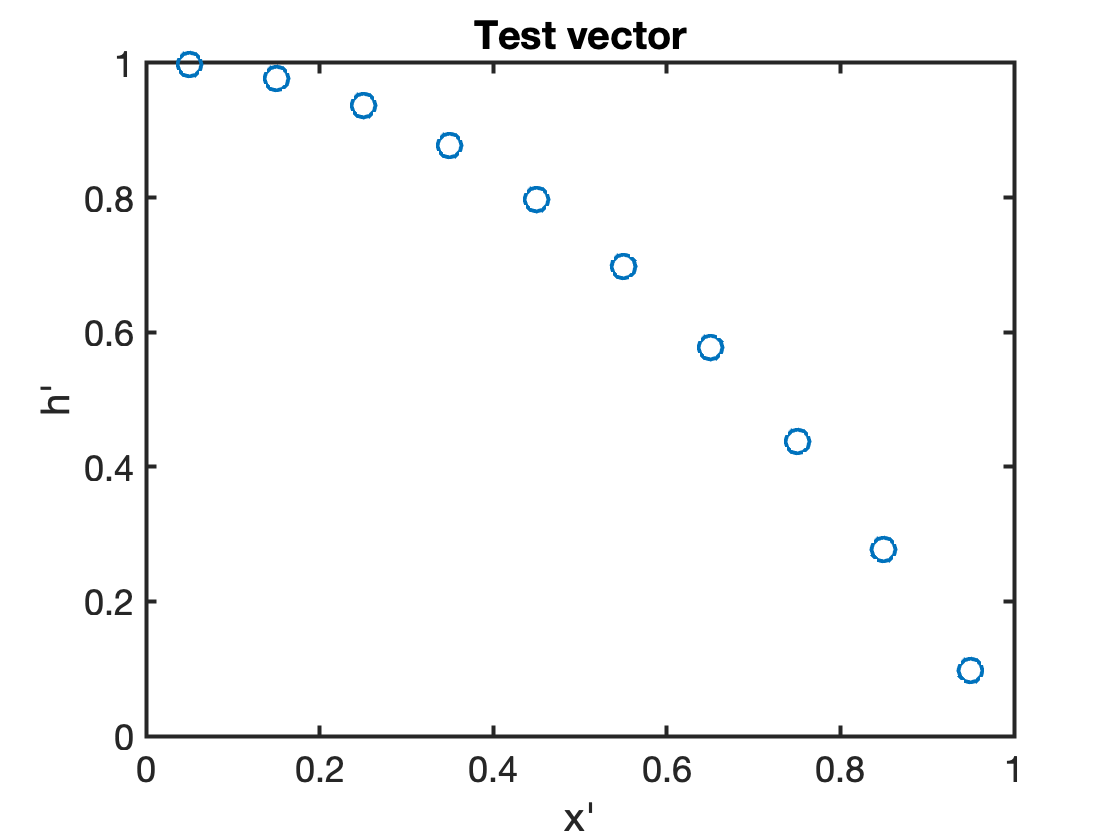

hD_test = 1-Grid.xc.^2;
plot(Grid.xc,hD_test,'o')
xlabel 'x''', ylabel 'h'''
title 'Test vector'

It is useful to visualize the sparsity pattern of the Jacobian matrix, it is the same as that of the discrete operators. In 1D this means it is tri-diagonal, like the discrete Laplacian `L = -D*G`.

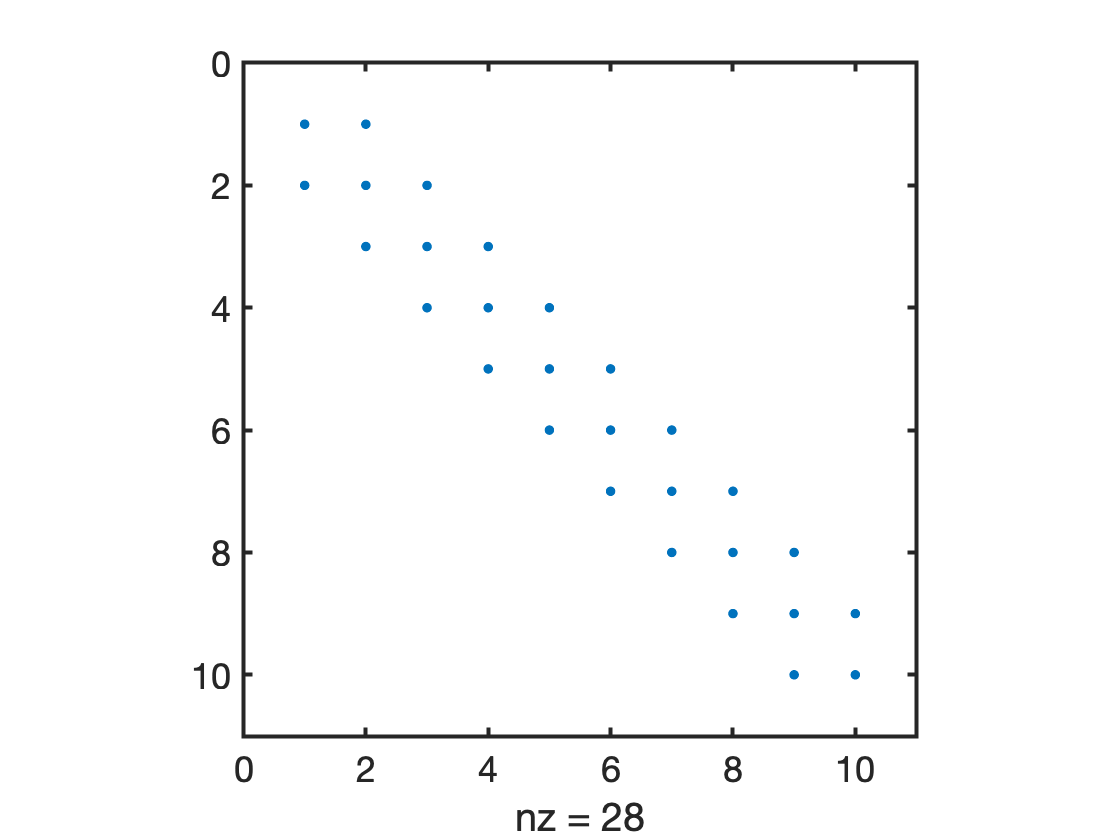

Jac_ana = Jac(hD_test);
spy(Jac_ana)

## Finite difference approximation of the Jacobian

For the residual $\mathbf{r}(\mathbf{u})$, the entries in the Jacobian can be approximated with finite differences as

$J_{ij} = \frac{\partial r_i}{\partial u_j} \approx \frac{r_i(u_j+\epsilon)-r_i(u_j)}{\epsilon}$ for $0< \epsilon \ll 1$

In Matlab we can vectorize this partially by computing the derivatives of all $r_i$'s with respect to a particular $u_j$ at the same time. But we still have to loop over the `N` unkonwns. Note, this is the only code in this class where we use a for-look to look over the unknowns!!! It is slow, but this does not matter because we only use this in testing. 

u = hD_test;
eps_jac = 1e-6

eps_jac = 1.0000e-06

Jac_num = spalloc(Grid.Nx,Grid.Nx,nnz(D*G)); % initialize the sparse Jacobian
u_perturb=u;
for i=1:Grid.Nx
   u_perturb(i)=u_perturb(i)+eps_jac;
   Jac_num(:,i)=(res(u_perturb)-res(u))/eps_jac;
   u_perturb(i)=u(i);
end

% Jac_num = comp_jacobian(res,hD_test,eps_jac)
Jac_num = full(Jac_num)

Jac_num =   -99.7500   97.7501         0         0         0         0         0         0         0         0
   99.7500 -195.5001   93.7500         0         0         0         0         0         0         0
         0   97.7501 -187.5001   87.7501         0         0         0         0         0         0
         0         0   93.7500 -175.5001   79.7501         0         0         0         0         0
         0         0         0   87.7500 -159.5001   69.7500         0         0         0         0
         0         0         0         0   79.7501 -139.5001   57.7501         0         0         0
         0         0         0         0         0   69.7501 -115.5001   43.7501         0         0
         0         0         0         0         0         0   57.7500  -87.5001   27.7501         0
         0         0         0         0         0         0         0   43.7500  -55.5001    9.7501
         0         0         0         0         0         0         0         0 

Jac_ana = full(Jac_ana)

Jac_ana =   -99.7500   97.7500         0         0         0         0         0         0         0         0
   99.7500 -195.5000   93.7500         0         0         0         0         0         0         0
         0   97.7500 -187.5000   87.7500         0         0         0         0         0         0
         0         0   93.7500 -175.5000   79.7500         0         0         0         0         0
         0         0         0   87.7500 -159.5000   69.7500         0         0         0         0
         0         0         0         0   79.7500 -139.5000   57.7500         0         0         0
         0         0         0         0         0   69.7500 -115.5000   43.7500         0         0
         0         0         0         0         0         0   57.7500  -87.5000   27.7500         0
         0         0         0         0         0         0         0   43.7500  -55.5000    9.7500
         0         0         0         0         0         0         0         0 

Jac_err = Jac_ana-Jac_num 

Jac_err = 	1.0e+-3 *

    0.0500   -0.0500         0         0         0         0         0         0         0         0
   -0.0500    0.1000   -0.0500         0         0         0         0         0         0         0
         0   -0.0500    0.1000   -0.0500         0         0         0         0         0         0
         0         0   -0.0500    0.1000   -0.0500         0         0         0         0         0
         0         0         0   -0.0500    0.1000   -0.0500         0         0         0         0
         0         0         0         0   -0.0500    0.1000   -0.0500         0         0         0
         0         0         0         0         0   -0.0500    0.1000   -0.0500         0         0
         0         0         0         0         0         0   -0.0500    0.1000   -0.0500         0
         0         0         0         0         0         0         0   -0.0500    0.1000   -0.0500
         0         0         0         0         0         0         

This can be compartmentalized in a function `comp_jacobian.m`. 

### Convergence of FD approximation

We can use this function to test the convergence of the finite difference approximation of the Jacobian

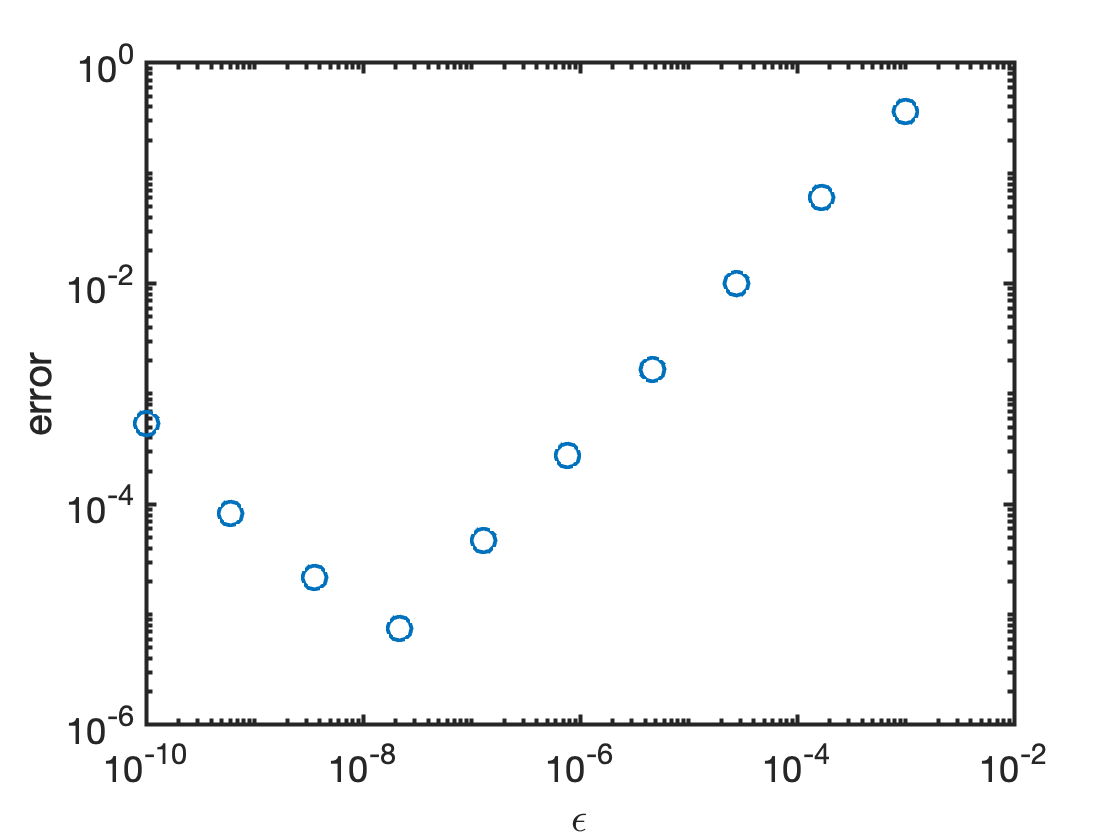

N_eps = 10;
eps_vec = logspace(-10,-3,N_eps);
Jana = Jac(hD_test);
for i = 1:N_eps
    Jnum = comp_jacobian(res,u,eps_vec(i));
    Jerr(i) = norm(Jnum(:)-Jana(:));
end
figure
loglog(eps_vec,Jerr,'o')
xlabel '\epsilon'
ylabel 'error'

Again we see the increase of the error in the limit of small $\epsilon$ due to round-off errors. A reasonable magnitude for the perturbation is beteen $10^{-4}$ and $10^{-8}$.

##  Solving unconfined aquifer problem with numerical Jacobian

For the unconfined aquifer problem the Newton-Raphson method converges in the same number of iteration as the analytical Jacobian for $\epsilon <10^{-4}$. However, as the system of equation increases the Jacobian becomes more expensive to compute, due to the for-loop.

%% Analytic solution
hD_ana = @(xD,Pi) sqrt(1+Pi^2-xD.^2);

%% Boundary conditions - for update!
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = 0;
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,I] = build_bnd(BC,Grid,I);

%% Newton iteration
tol = 1e-9; % convergence tolerance
nmax = 10;   % maximum number of iterations

% Initial guess
hD = ones(Grid.Nx,1);  
hD(BC.dof_dir) = hD_ana(Grid.xc(BC.dof_dir),Pi); % satisfy Dir BC so dhD = 0 on bnd! 

nres = norm(res(hD)); ndhD = 1; n = 0;
while (nres > tol || ndhD > tol) && n < nmax
%     J = Jac(hD);                    % analytic Jacobian
    J = comp_jacobian(res,hD,1e-3); % numerical Jacobian
    dhD = solve_lbvp(J,-res(hD),B,BC.g,N); 
    hD = hD + dhD;
    nres = norm(N'*res(hD)); ndhD = norm(N'*dhD);
    n = n+1;
    fprintf('it = %d: nres = %3.2e  ndhD = %3.2e\n',n,nres,ndhD)
    if n == 1; ndhD = 0; end % to allow exit on first iteration
    nres_Newton(n) = nres; ndhD_Newton(n) = ndhD;
end

it = 1: nres = 7.31e+00  ndhD = 4.49e-01
it = 2: nres = 4.99e-01  ndhD = 8.38e-02
it = 3: nres = 2.55e-03  ndhD = 4.55e-03
it = 4: nres = 2.17e-06  ndhD = 2.00e-05
it = 5: nres = 1.80e-09  ndhD = 1.68e-08
it = 6: nres = 1.49e-12  ndhD = 1.38e-11


function [J] = comp_jacobian(r,u,eps)
n=length(u);
J = spalloc(n,n,3*n);
u_perturb=u;
for i=1:n
   u_perturb(i)=u_perturb(i)+eps;
   J(:,i)=(r(u_perturb)-r(u))/eps;
   u_perturb(i)=u(i);
end
end